s = tf('s');

plant transfer function

G_p = 1 / (0.2 * s + 1);

controller transfer function

G_c = (500 * s + 50) / (100 * s^2 + s);

open-loop transfer function

G_open = G_c * G_p;

closed-loop transfer function

G_closed = feedback(G_open, 1);

Bode plot to check phase margin

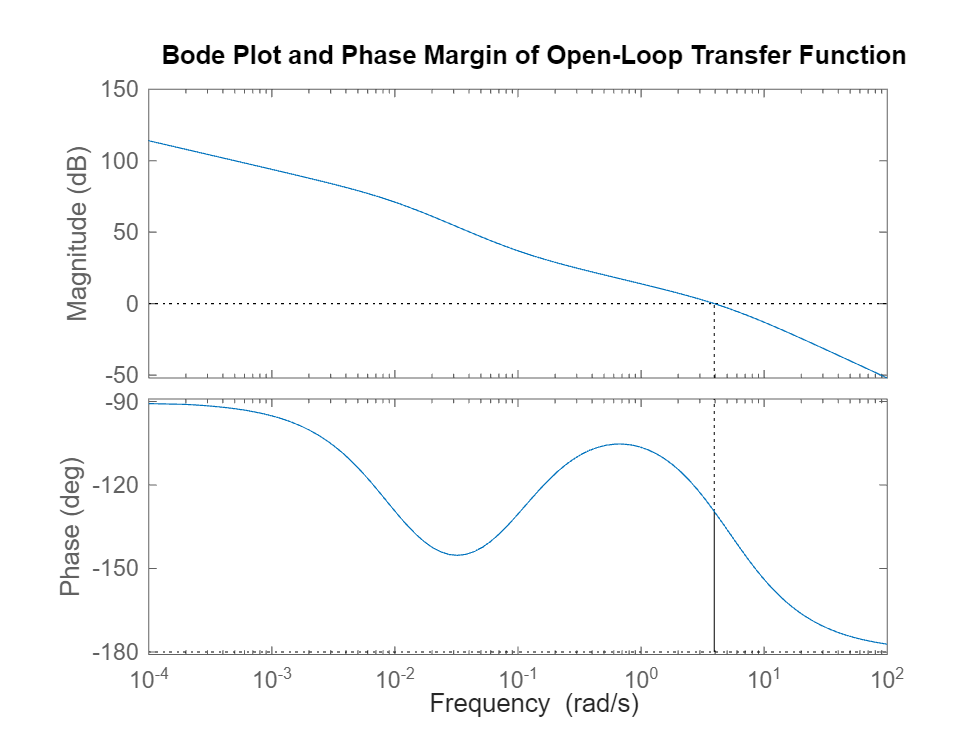

figure;
margin(G_open);
title('Bode Plot and Phase Margin of Open-Loop Transfer Function');

Check phase margin

[Gm, Pm, Wcg, Wcp] = margin(G_open);
fprintf('Phase Margin: %.2f degrees\n', Pm);

Phase Margin: 50.51 degrees


Calculate steady-state error for a ramp input

Kv = dcgain(s * G_open); % Velocity error constant
ess_ramp = 1 / Kv;       % Steady-state error for ramp input

fprintf('Velocity error constant (Kv): %.2f\n', Kv);

Velocity error constant (Kv): 50.00


fprintf('Steady-state error for ramp input: %.2f%%\n', ess_ramp * 100);

Steady-state error for ramp input: 2.00%



if ess_ramp <= 0.02 && Pm > 48
    disp('The design meets both the steady-state error and phase margin requirements.');
else
    disp('The design does not meet one or both of the requirements.');
end

step response of the closed-loop system

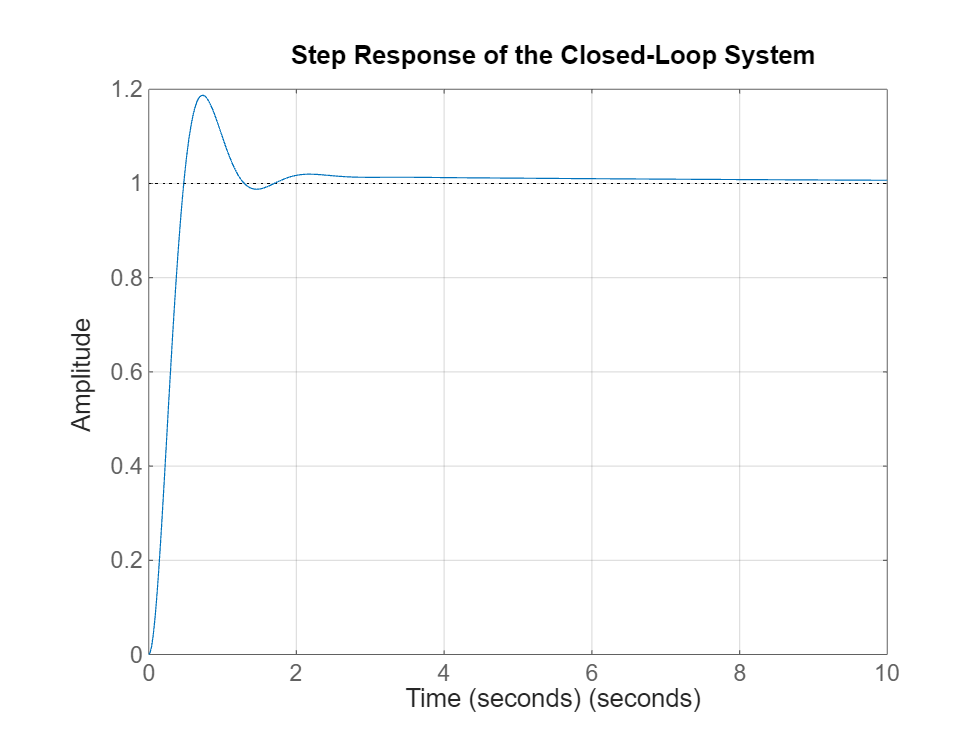

The design meets both the steady-state error and phase margin requirements.


figure;
step(G_closed);
title('Step Response of the Closed-Loop System');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;